# Assignment 1 - Aero Engine Technologies

## LEAP-1A Turbofan

Characteristics:

clear all
close all
clc

pi_inlet = 0.98; %Inlet Pressure Ratio
m = 173;%Engine Air Mass flow rate [kg/s]
BPR = 12; %Bypass Ratio
FPR = 1.4; %Fan Pressure Ratio
pi_LPC = 1.7; %LPC Pressure Ratio
pi_HPC = 12.5; %HPC Pressure Ratio
TIT = 1400; %Turbine Inlet Temperature [K]
eta_fan = 0.9; %Fan isentropic efficiency
eta_comp = 0.92; %LPC & HPC isentropic efficiency
eta_turb = 0.9; %LPT & HPT isentropic efficiency
eta_mec = 0.99; %Mechanical efficiency
eta_comb = 0.995; %Combustor efficiency
pi_comb = 0.96; %Combustor pressure ratio
eta_noz = 0.98; %Nozzle efficiency
M = 0.78; %Mach number
h = 10668; %Altitude [m]
T_amb = 218.8; %Ambient Temperature [K]
P_amb = 23842; %Ambient Pressure [Pa]
R = 287; %Gas constant [J/(Kg*K)]
LHV = 43000000; %Fuel Calorific Value [J/Kg]
cp_a = 1000; %Specific heat at constant pressure for air [J/(Kg*K)]
g_a = 1.4; %Specific heat ratio for air
cp_gas = 1150; %Specific heat at constant pressure for combusted gases [J/(Kg*K)]
g_gas = 1.33; %Specific heat ratio for combusted gases

## Part 1: Cycle calculation

### Inlet:

First the total quantities are calculated at the station 0, then at the station 2

v_0 = M*sqrt(g_a*R*T_amb);
T_ta = T_amb*(1+ ((g_a-1)/2)*M^2);
T_t2 = T_ta;
P_ta = P_amb*(1+ ((g_a-1)/2)*M^2)^(g_a/(g_a-1));
P_t2er = P_amb*(1+ pi_inlet*((g_a-1)/2)*M^2)^(g_a/(g_a-1));
P_t2 = P_ta*pi_inlet;
err = 100*(P_t2er-P_t2)/P_t2er; %Still, from one to the other there is no big difference, so it is alright, but I prefer treating a pressure ratio as a pressure ratio

### Fan:

Here it is calculated the work required to move the fan, divided in a contribution from the cold flow and another from the hot flow

P_t21 = P_t2*FPR;
P_t13 = P_t21;
T_t21 = T_t2*(1 + (1/eta_fan)*(FPR^((g_a-1)/g_a) -1));
T_t13 = T_t21;
W_fan = m*cp_a*(T_t21-T_t2);
m_hot = m/(BPR+1);
m_cold = m_hot*BPR;
W_fan_hot = m_hot*cp_a*(T_t21-T_t2);
W_fan_cold = m_cold*cp_a*(T_t21-T_t2);


### Compressors:

Here it is calculated the work required to move the LPC and the HPC

P_t25 = P_t21*pi_LPC;
P_t3 = P_t25*pi_HPC;
T_t25 = T_t21*(1 + (1/eta_comp)*(pi_LPC^((g_a-1)/g_a) -1));
T_t3 = T_t25*(1 + (1/eta_comp)*(pi_HPC^((g_a-1)/g_a) -1));
W_LPC = m_hot*cp_a*(T_t25-T_t21);
W_HPC = m_hot*cp_a*(T_t3-T_t25);


### Combustion chamber:

In this part the total values of T and P are calculated at the station 4, adding fuel and the energy due to the combustion

%m_f = (m_hot*cp_a*(TIT-T_t3))/(eta_comb*LHV); %%Are you sure that this is cp_a and not cp_gas? A better version is shown in the next line, even though conceptually it is not correct, because I am assuming a value for cp_gas and I don't know the composition yet
m_f = (m_hot*(cp_gas*TIT-cp_a*T_t3))/(eta_comb*LHV);
m_gas = m_hot + m_f;
P_t4 = P_t3*pi_comb;


### HPT:

Here it is calculated the work obtained moving the HPT, obtaining as a result also the total values at the station 45

W_HPT = W_HPC/eta_mec;
T_t45 = TIT-W_HPT/(m_gas*cp_gas);
P_t45 = P_t4*(1- (1/eta_turb)*(1- T_t45/TIT))^(g_gas/(g_gas-1));


### LPT:

Here it is calculated the work obtained moving the LPT, obtaining as a result also the total values at the station 5

W_LPT = (W_LPC+W_fan)/eta_mec;
W_4g = (W_LPC+W_fan_hot)/eta_mec;
T_tg = T_t45- W_4g/(m_gas*cp_gas);
T_t5 = T_t45- W_LPT/(m_gas*cp_gas);
P_t5 = P_t45*(1- (1/eta_turb)*(1- T_t5/T_t45))^(g_gas/(g_gas-1));
P_tg = P_t45*(1- (1/eta_turb)*(1- T_tg/T_t45))^(g_gas/(g_gas-1));
P_8is = P_amb;
T_8is = T_tg*(P_8is/P_tg)^((g_gas-1)/g_gas);
P_18is = P_amb;
T_18is = T_t13*(P_18is/P_t13)^((g_a-1)/g_a);
% W_gg = m_gas*cp_gas*(T_tg-T_8is) + m_cold*cp_a*(T_t13-T_18is)
W_gg = m_gas*cp_gas*(T_tg-T_8is);

### Core Nozzle:

It is now shown how the flow evolves through the core nozzle, until the end of the "open" cycle, that is station 8

T_t7 = T_t5;
T_t8 = T_t7;
P_t7 = P_t5;
Crit_ratioc = (1- (1/eta_noz)*((g_gas-1)/(g_gas+1)))^(-g_gas/(g_gas-1));
if P_t7/P_amb >= Crit_ratioc %Critical nozzle or chocked nozzle
    M_8 = 1;
    T_8 = T_t7*(2/(g_gas+1));
    P_8 = P_t7/(Crit_ratioc);
    v_8 = sqrt(g_gas*R*T_8);
    r_8 = P_8/(R*T_8);
    A_8 = m_gas/(r_8*v_8);
else %unchocked nozzle
    P_8 = P_amb;
    M_8 = sqrt((2/(g_gas-1))*((P_t7/P_8)^((g_gas-1)/g_gas) -1));
    T_8 = T_t8/(1 + ((g_gas-1)/2)*M_8^2);
    v_8 = sqrt(g_gas*R*T_8);
    r_8 = P_8/(R*T_8);
    A_8 = m_gas/(r_8*v_8);
end
P_t8 = P_8*(1 + ((g_gas-1)/2)*M_8^2)^(g_gas/(g_gas-1));


### Bypass Nozzle:

It is now shown how the flow evolves through the bypass nozzle, until the end of the "open" cycle, that is station 18

T_t16 = T_t13;
P_t16 = P_t13;
Crit_ratiobp = (1- (1/eta_noz)*((g_a-1)/(g_a+1)))^(-g_a/(g_a-1));
if P_t16/P_amb >= Crit_ratiobp %Critical nozzle or chocked nozzle
    M_18 = 1;
    T_18 = T_t16*(2/(g_a+1));
    P_18 = P_t16/(Crit_ratiobp);
    v_18 = sqrt(g_a*R*T_18);
    r_18 = P_18/(R*T_18);
    A_18 = m_cold/(r_18*v_18);
else %unchocked nozzle
    P_18 = P_amb;
    M_18 = sqrt((2/(g_a-1))*((P_t16/P_18)^((g_a-1)/g_a) -1));
    T_18 = T_t16/(1 + ((g_a-1)/2)*M_18^2);
    v_18 = sqrt(g_a*R*T_18);
    r_18 = P_18/(R*T_18);
    A_18 = m_cold/(r_18*v_18);
end
P_t18 = P_18*(1 + ((g_a-1)/2)*M_18^2)^(g_a/(g_a-1));

### Performance parameters:

Now the results obtained are used to calculate Thrust and SFC at cruise condition

F_core = m_gas*(v_8-v_0) + A_8*(P_8-P_amb);
F_bp = m_cold*(v_18-v_0) + A_18*(P_18-P_amb);
F = F_core+F_bp;
TSFC = m_f/F;


### T-S diagram:

Given the values of P and T, they are plotted on the T-S diagram

Assuming an ideal, calorically perfect gas and a reversible transformation:

From the 1st Law we know that:  dq = de + pdv;

Applying the definition of entropy: ds =de/T + pdv/T

And given that the gas is ideal and calorically perfect: ds =cdv/T + pdv/T and T = pv/R

ds = c_v (\gamma dv/v + dp/p)

ds = c_v d(log(pv^\gamma))

s = c_v (log(pv^\gamma)) +const

Also, we can put it in terms of s, p and T:

s = (c_p )ln(T/(p^((g-1)/g))) + const

We start from the first transformation: the change from static to total values of T and p, but we choose to consider the first constant entropy equal to 3796 J/(Kg*K), and that is the entropy at 273.15 K and 100000 Pa (from https://www.engineeringtoolbox.com/air-properties-d_156.html)

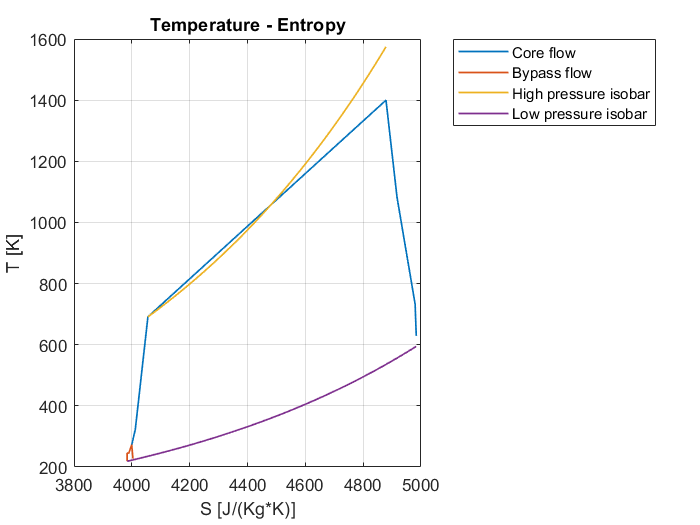

s_amb = 3796 + cp_a*log((T_amb/273.15)*(100000/P_amb)^((g_a-1)/g_a));
s_0 = s_amb + cp_a*log((T_ta/T_amb)*(P_amb/P_ta)^((g_a-1)/g_a));
s_2 = s_0 + cp_a*log((T_t2/T_ta)*(P_ta/P_t2)^((g_a-1)/g_a));
s_21 = s_2 + cp_a*log((T_t21/T_t2)*(P_t2/P_t21)^((g_a-1)/g_a));
s_13 = s_2 + cp_a*log((T_t13/T_t2)*(P_t2/P_t13)^((g_a-1)/g_a));
s_25 = s_21 + cp_a*log((T_t25/T_t21)*(P_t21/P_t25)^((g_a-1)/g_a));
s_3 = s_25 + cp_a*log((T_t3/T_t25)*(P_t25/P_t3)^((g_a-1)/g_a));
s_4 = s_3 + cp_gas*log((TIT/T_t3)*(P_t3/P_t4)^((g_gas-1)/g_gas));
s_45 = s_4 + cp_gas*log((T_t45/TIT)*(P_t4/P_t45)^((g_gas-1)/g_gas));
s_5 = s_45 + cp_gas*log((T_t5/T_t45)*(P_t45/P_t5)^((g_gas-1)/g_gas));
s_7 = s_5;
s_8 = s_7 + cp_gas*log((T_8/T_t7)*(P_t7/P_8)^((g_gas-1)/g_gas));
s_16 = s_13;
s_18 = s_16 + cp_a*log((T_18/T_t16)*(P_t16/P_18)^((g_a-1)/g_a));
S = [s_amb s_0 s_2 s_21 s_25 s_3 s_4 s_45 s_5 s_7 s_8 ];
TS = [T_amb T_ta T_t2 T_t21 T_t25 T_t3 TIT T_t45 T_t5 T_t7 T_8 ];
S1 = [s_amb s_0 s_2 s_13 s_16 s_18 ];
TS1 = [T_amb T_ta T_t2 T_t13 T_t16 T_18 ];
S_lowp = linspace(s_amb,s_8);
S_highp = linspace(s_3,s_4);
T_lowp(1) = T_amb;
for i = 2:size(S_lowp,2)
    T_lowp(i) = T_lowp(i-1)*exp((S_lowp(i)-S_lowp(i-1))/cp_a);
end
T_highp(1) = T_t3;
for i = 2:size(S_highp,2)
    T_highp(i) = T_highp(i-1)*exp((S_highp(i)-S_highp(i-1))/cp_a);
end

figure("Name","Temperature - Entropy")
plot(S, TS, "LineWidth",1)
hold on
plot(S1, TS1, "LineWidth",1)
hold on
plot(S_highp,T_highp,"LineWidth",1)
hold on
plot(S_lowp,T_lowp, "LineWidth",1)
title("Temperature - Entropy")
xlabel("S [J/(Kg*K)]")
ylabel("T [K]")
legend(["Core flow"; "Bypass flow"; "High pressure isobar"; "Low pressure isobar"], "Location","bestoutside")
grid("on")

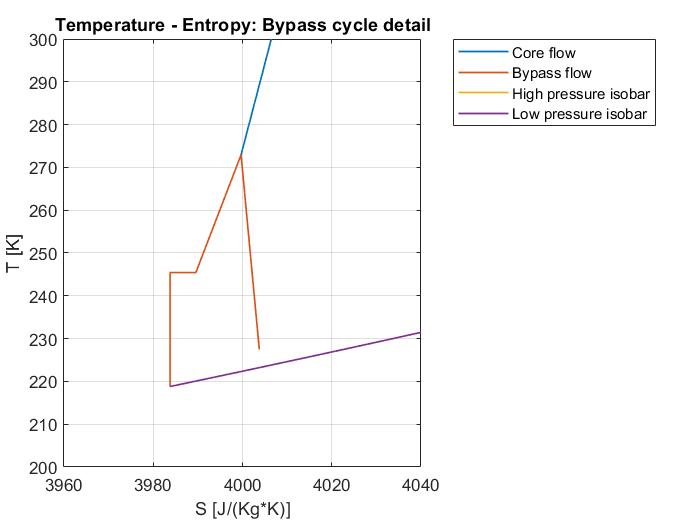

figure("Name","Temperature - Entropy: Bypass cycle detail")
plot(S, TS, "LineWidth",1)
hold on
plot(S1, TS1, "LineWidth",1)
hold on
plot(S_highp,T_highp,"LineWidth",1)
hold on
plot(S_lowp,T_lowp, "LineWidth",1)
title("Temperature - Entropy: Bypass cycle detail")
xlabel("S [J/(Kg*K)]")
ylabel("T [K]")
legend(["Core flow"; "Bypass flow"; "High pressure isobar"; "Low pressure isobar"], "Location","bestoutside")
grid("on")
xlim([3960 4040])
ylim([200.0 300])